**Submitted By**

**Hridya Divakaran : V00970167**

**Sanjana Arora : V00966221**

clear;
clc;
% loading the variables from the exercise 1
a = load("ex1.mat")

a = struct with fields:
          Da: [3×3 double]
          Db: [3×3 double]
          Dc: [3×3 double]
           K: 1000
          Va: [3×3 double]
          Vb: [3×3 double]
          Vc: [3×3 double]
           W: [1000×3 double]
         ans: [-2.0000 -5.0000 -5]
    filename: 'ex1.mat'
         muA: [3×1 double]
         muB: [3×1 double]
         muC: [3×1 double]
         muT: [3×1 double]
      sigmaA: [3×3 double]
      sigmaB: [3×3 double]
      sigmaC: [3×3 double]
      sigmaT: [3×3 double]
    testdata: [50×3 double]
           y: [1000×3 double]
           z: [1000×3 double]



% introducing 50 outlier data points in class A each at random mahalanobis
% distances
outlier_data_classA = outlier_point(a.sigmaA, a.muA, 50, a.y)

l =    -2.2127    5.6775    7.3315
   -1.3820    7.2013    9.5850
   -0.7868    3.0579    6.7880
    1.2261    3.2276    7.5618
    0.4952    3.4002    7.4148
   -1.4164    6.4188    9.3973
   -3.3674    3.2100    8.3822
    0.7175    4.1200    5.6366
    2.3944    6.6636    9.4128
   -0.9580    2.8548    6.1026


outlier_data_classA =    -2.2127    5.6775    7.3315
   -1.3820    7.2013    9.5850
   -0.7868    3.0579    6.7880
    1.2261    3.2276    7.5618
    0.4952    3.4002    7.4148
   -1.4164    6.4188    9.3973
   -3.3674    3.2100    8.3822
    0.7175    4.1200    5.6366
    2.3944    6.6636    9.4128
   -0.9580    2.8548    6.1026



newmuA = mean(outlier_data_classA);
newcovA = cov(outlier_data_classA);

% introducing 20 outlier datapoints in class B each at random mahalanobis distance
outlier_data_classB = outlier_point(a.sigmaB, a.muB, 20, a.z)

l =    10.5854    6.6235    4.2463
    8.9943    5.5749    5.8479
    6.7957    4.1701    7.6778
   10.5014    5.4883    5.1728
   11.9646    4.9122    3.6653
    9.0677    5.9706    4.3526
   10.2332    5.6636    4.2792
    8.1166    4.1976    6.2368
   11.2296    4.3901    4.4488
   13.3883    5.2855    3.0555


outlier_data_classB =    10.5854    6.6235    4.2463
    8.9943    5.5749    5.8479
    6.7957    4.1701    7.6778
   10.5014    5.4883    5.1728
   11.9646    4.9122    3.6653
    9.0677    5.9706    4.3526
   10.2332    5.6636    4.2792
    8.1166    4.1976    6.2368
   11.2296    4.3901    4.4488
   13.3883    5.2855    3.0555


newmuB = mean(outlier_data_classA);
newcovB = cov(outlier_data_classA);

% introducing 10 outlier datapoints in class C each at random mahalanobis distance
outlier_data_classC = outlier_point(a.sigmaC, a.muC, 10, a.W)

l =    -5.5120   -4.2368   -5.1951
   -1.4882   -5.6711   -5.4325
   -2.0602   -5.3337   -4.7779
   -5.7291   -6.1851   -6.5630
   -2.1725   -3.6372   -6.3555
   -1.1413   -4.4536   -5.5310
   -3.0586   -8.0545   -6.8555
   -1.2453   -3.2524   -0.9544
   -2.9090   -6.0060   -6.5374
    1.8328   -4.5369   -3.7018


outlier_data_classC =    -5.5120   -4.2368   -5.1951
   -1.4882   -5.6711   -5.4325
   -2.0602   -5.3337   -4.7779
   -5.7291   -6.1851   -6.5630
   -2.1725   -3.6372   -6.3555
   -1.1413   -4.4536   -5.5310
   -3.0586   -8.0545   -6.8555
   -1.2453   -3.2524   -0.9544
   -2.9090   -6.0060   -6.5374
    1.8328   -4.5369   -3.7018


newmuC = mean(outlier_data_classA);
newcovC = cov(outlier_data_classA);

**Case 1** Neural Network Boundary after introducing outlier data point in class A

inputVector = horzcat(outlier_data_classA', a.z',a.W')

inputVector =    -2.2127   -1.3820   -0.7868    1.2261    0.4952   -1.4164   -3.3674    0.7175    2.3944   -0.9580    1.6896    5.2320   -1.1619   -6.5251    1.0880   -2.9826   -2.0270    1.4307    1.3960   -0.1224   -2.2141    4.1305   -2.3686   -3.3158   -3.3048   -1.9041   -1.2653   -5.5240   -1.0970   -3.1594    0.1152   -2.7072    3.1286   -4.8848   -0.5547   -0.3689    0.3876   -3.2732    1.8704    0.5337    4.9182   -0.8032   -3.2803    6.6613    0.8779    0.0045    1.0392   -4.7136    0.5060    0.9628
    5.6775    7.2013    3.0579    3.2276    3.4002    6.4188    3.2100    4.1200    6.6636    2.8548    6.5055    6.4275    6.3974    3.8046    6.1412    1.7486    3.7355    2.8548   -0.1673    2.0825    7.5688    4.4228    4.9184   -0.7536    4.6185    4.3594    5.2093    3.7239    5.0829    6.6086    2.9246    3.4266    5.1092    6.0277    6.6620    1.3668    4.3124    6.6992    1.7320    4.9207    6.7317    2.8087    1.7246    3.9237    1.3013    7.8677    0.2525    2.4491    3

trueclassindices = [ 1 2 3];
One_hot_encoded = full(ind2vec(trueclassindices,3))

One_hot_encoded =      1     0     0
     0     1     0
     0     0     1



% 1003 as we now have 1003 data points for class A
label_A = repmat(One_hot_encoded(1,:), 1050,1);
label_B = repmat(One_hot_encoded(2,:),1000,1);
label_C = repmat(One_hot_encoded(3,:), 1000,1);
target_label = horzcat(label_A',label_B',label_C');

% Training the neural network
inputs = inputVector;
targets = target_label;
hiddenLayerSize = 50;
net = patternnet(hiddenLayerSize);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
rng(1)
[net,tr] = train(net,inputs,targets);
view(net)

points= vol3D([-15 20 -15 20 -15 20],200);
results = net(points');
g = results'

g =     0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000


**Plotting the decision Boundary**

[boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)

boundary_1 =    -5.5025   19.8241   -6.3819
   -4.6231   19.4724   -6.3819
   -4.4472   19.8241   -6.7337
   -4.0955   19.4724   -6.5578
   -3.9196   19.8241   -6.9095
   -3.3920   19.6482   -6.9095
   -3.2161   20.0000   -7.2613
   -3.0402   19.2965   -6.7337
   -2.6884   18.9447   -6.5578
   -2.6884   19.8241   -7.2613


boundary_2 =   -15.0000  -15.0000    4.5226
  -15.0000  -14.8241    4.5226
  -15.0000  -14.6482    4.5226
  -15.0000  -12.8894    4.3467
  -15.0000   -9.3719    3.4673
  -15.0000   -5.6784    2.4121
  -15.0000   -2.5126    1.5327
  -15.0000    7.5126   -1.1055
  -15.0000   11.9095   -2.8643
  -15.0000   16.6583   -4.7990


boundary_3 =    -7.7889   20.0000   -4.2714
   -7.6131   19.8241   -4.6231
   -7.6131   20.0000   -3.7437
   -7.4372   19.8241   -3.7437
   -7.2613   19.6482   -3.9196
   -7.2613   19.8241   -3.2161
   -7.0854   19.4724   -4.4472
   -7.0854   19.4724   -4.2714
   -7.0854   19.6482   -3.2161
   -7.0854   19.8241   -2.8643


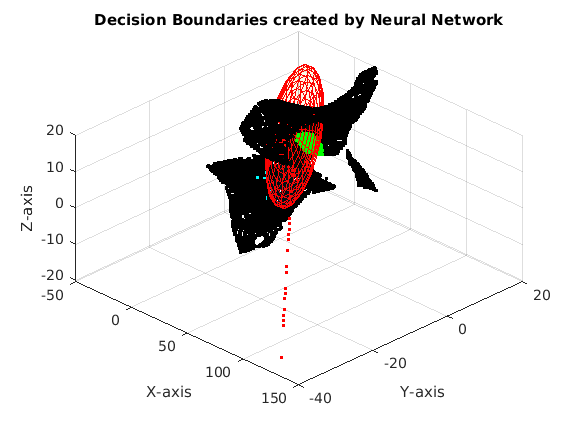

Classes(outlier_data_classA,newmuA',newcovA,a.z,a.muB,a.sigmaB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2, boundary_3,[0 0 0])
title('Decision Boundaries created by Neural Network')

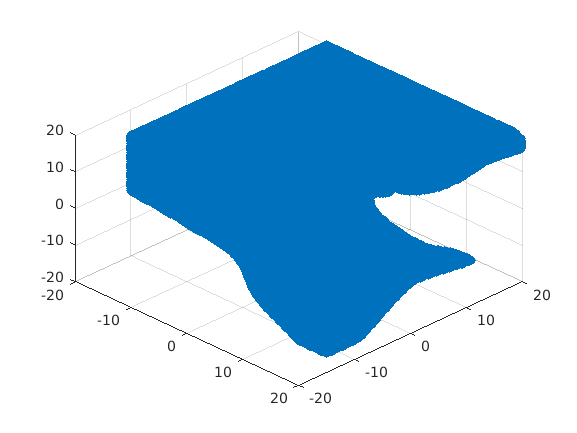

PlotNN_outlierA(g, points)

**Case 2** Neural Network Boundary after introducing outlier data point in class B

inputVector = horzcat(a.y', outlier_data_classB',a.W')

inputVector =    -2.2127   -1.3820   -0.7868    1.2261    0.4952   -1.4164   -3.3674    0.7175    2.3944   -0.9580    1.6896    5.2320   -1.1619   -6.5251    1.0880   -2.9826   -2.0270    1.4307    1.3960   -0.1224   -2.2141    4.1305   -2.3686   -3.3158   -3.3048   -1.9041   -1.2653   -5.5240   -1.0970   -3.1594    0.1152   -2.7072    3.1286   -4.8848   -0.5547   -0.3689    0.3876   -3.2732    1.8704    0.5337    4.9182   -0.8032   -3.2803    6.6613    0.8779    0.0045    1.0392   -4.7136    0.5060    0.9628
    5.6775    7.2013    3.0579    3.2276    3.4002    6.4188    3.2100    4.1200    6.6636    2.8548    6.5055    6.4275    6.3974    3.8046    6.1412    1.7486    3.7355    2.8548   -0.1673    2.0825    7.5688    4.4228    4.9184   -0.7536    4.6185    4.3594    5.2093    3.7239    5.0829    6.6086    2.9246    3.4266    5.1092    6.0277    6.6620    1.3668    4.3124    6.6992    1.7320    4.9207    6.7317    2.8087    1.7246    3.9237    1.3013    7.8677    0.2525    2.4491    3

trueclassindices = [ 1 2 3];
One_hot_encoded = full(ind2vec(trueclassindices,3))

One_hot_encoded =      1     0     0
     0     1     0
     0     0     1



% 1003 as we now have 1003 data points for class A
label_A = repmat(One_hot_encoded(1,:), 1000,1);
label_B = repmat(One_hot_encoded(2,:),1020,1);
label_C = repmat(One_hot_encoded(3,:), 1000,1);
target_label = horzcat(label_A',label_B',label_C');

% Training the neural network
inputs = inputVector;
targets = target_label;
hiddenLayerSize = 50;
net2 = patternnet(hiddenLayerSize);
net2.divideParam.trainRatio = 70/100;
net2.divideParam.valRatio = 15/100;
net2.divideParam.testRatio = 15/100;
[net2,tr] = train(net2,inputs,targets);
view(net2)

points= vol3D([-15 20 -15 20 -15 20],200);
results = net2(points');
g = results'

g =     0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000


**Plotting the decision Boundary**

[boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)

boundary_1 =   -15.0000  -12.3618   19.1206
  -15.0000  -12.1859   18.7688
  -15.0000  -10.6030   15.7789
  -15.0000  -10.4271   15.4271
  -15.0000  -10.2513   15.0754
  -15.0000   -9.1960   12.7889
  -14.8241  -11.6583   17.8894
  -14.8241   -9.7236   14.0201
  -14.8241   -8.8442   12.0854
  -14.6482  -12.7136   20.0000


boundary_2 =   -15.0000   -5.5025    6.9849
  -15.0000   -3.5678    4.8744
  -15.0000   -3.0402    4.1709
  -15.0000   -2.6884    3.6432
  -15.0000   -1.9849    2.2362
  -15.0000   -1.8090    1.7085
  -15.0000   -1.6332    1.1809
  -15.0000   -1.4573    0.6533
  -15.0000   -1.2814   -0.0503
  -15.0000   -1.2814    0.1256


boundary_3 =   -15.0000   -0.9296    7.6884
  -15.0000    0.8291    7.1608
  -15.0000    1.1809    6.9849
  -15.0000    3.1156    6.1055
  -15.0000    3.4673    5.9296
  -15.0000    3.9950    5.7538
  -15.0000    6.1055   19.4724
  -15.0000    6.4573    6.1055
  -15.0000    6.4573   17.7136
  -15.0000    6.6332    6.2814


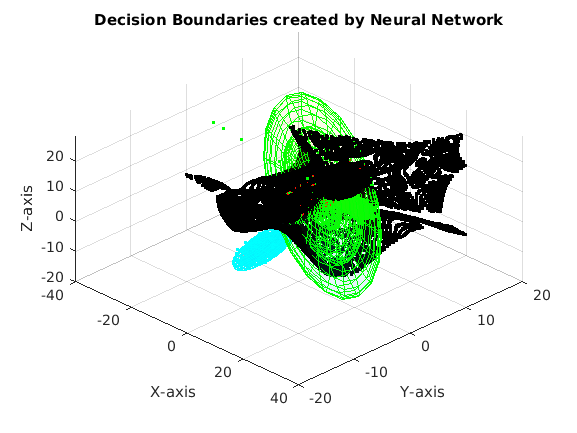

Classes(a.y,a.muA,a.sigmaA,outlier_data_classB,newmuB',newcovB,a.W,a.muC,a.sigmaC,boundary_1,boundary_2, boundary_3,[0 0 0])
title('Decision Boundaries created by Neural Network')

PlotNN_outlierA(g, points)

**Case 3** Neural Network Boundary after introducing outlier data point in class C

inputVector = horzcat(a.y', a.z',outlier_data_classC')

inputVector =    -2.2127   -1.3820   -0.7868    1.2261    0.4952   -1.4164   -3.3674    0.7175    2.3944   -0.9580    1.6896    5.2320   -1.1619   -6.5251    1.0880   -2.9826   -2.0270    1.4307    1.3960   -0.1224   -2.2141    4.1305   -2.3686   -3.3158   -3.3048   -1.9041   -1.2653   -5.5240   -1.0970   -3.1594    0.1152   -2.7072    3.1286   -4.8848   -0.5547   -0.3689    0.3876   -3.2732    1.8704    0.5337    4.9182   -0.8032   -3.2803    6.6613    0.8779    0.0045    1.0392   -4.7136    0.5060    0.9628
    5.6775    7.2013    3.0579    3.2276    3.4002    6.4188    3.2100    4.1200    6.6636    2.8548    6.5055    6.4275    6.3974    3.8046    6.1412    1.7486    3.7355    2.8548   -0.1673    2.0825    7.5688    4.4228    4.9184   -0.7536    4.6185    4.3594    5.2093    3.7239    5.0829    6.6086    2.9246    3.4266    5.1092    6.0277    6.6620    1.3668    4.3124    6.6992    1.7320    4.9207    6.7317    2.8087    1.7246    3.9237    1.3013    7.8677    0.2525    2.4491    3

trueclassindices = [ 1 2 3];
One_hot_encoded = full(ind2vec(trueclassindices,3))

One_hot_encoded =      1     0     0
     0     1     0
     0     0     1


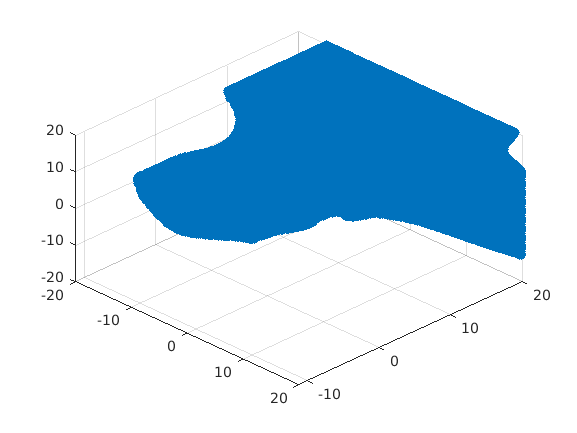


% 1003 as we now have 1003 data points for class A
label_A = repmat(One_hot_encoded(1,:), 1000,1);
label_B = repmat(One_hot_encoded(2,:),1000,1);
label_C = repmat(One_hot_encoded(3,:), 1010,1);
target_label = horzcat(label_A',label_B',label_C');

% Training the neural network
inputs = inputVector;
targets = target_label;
hiddenLayerSize = 50;
net3 = patternnet(hiddenLayerSize);
net3.divideParam.trainRatio = 70/100;
net3.divideParam.valRatio = 15/100;
net3.divideParam.testRatio = 15/100;
[net3,tr] = train(net3,inputs,targets);

view(net3)

points= vol3D([-15 20 -15 20 -15 20],200);
results = net(points');
g = results'

g =     0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000
    0.0000    0.0000    1.0000


**Plotting the decision Boundary**

[boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)

boundary_1 =    -5.5025   19.8241   -6.3819
   -4.6231   19.4724   -6.3819
   -4.4472   19.8241   -6.7337
   -4.0955   19.4724   -6.5578
   -3.9196   19.8241   -6.9095
   -3.3920   19.6482   -6.9095
   -3.2161   20.0000   -7.2613
   -3.0402   19.2965   -6.7337
   -2.6884   18.9447   -6.5578
   -2.6884   19.8241   -7.2613


boundary_2 =   -15.0000  -15.0000    4.5226
  -15.0000  -14.8241    4.5226
  -15.0000  -14.6482    4.5226
  -15.0000  -12.8894    4.3467
  -15.0000   -9.3719    3.4673
  -15.0000   -5.6784    2.4121
  -15.0000   -2.5126    1.5327
  -15.0000    7.5126   -1.1055
  -15.0000   11.9095   -2.8643
  -15.0000   16.6583   -4.7990


boundary_3 =    -7.7889   20.0000   -4.2714
   -7.6131   19.8241   -4.6231
   -7.6131   20.0000   -3.7437
   -7.4372   19.8241   -3.7437
   -7.2613   19.6482   -3.9196
   -7.2613   19.8241   -3.2161
   -7.0854   19.4724   -4.4472
   -7.0854   19.4724   -4.2714
   -7.0854   19.6482   -3.2161
   -7.0854   19.8241   -2.8643


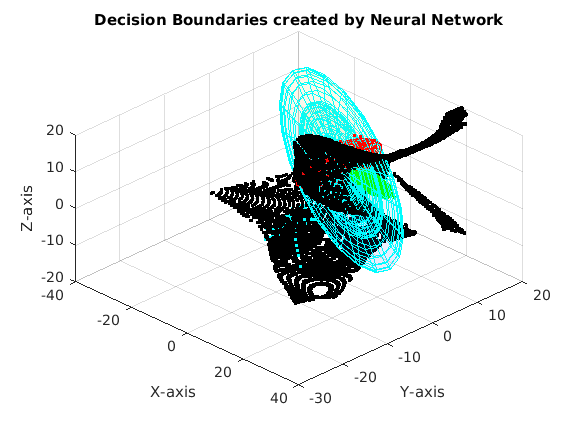

Classes(a.y,a.muA,a.sigmaA,a.z,a.muB,a.sigmaB,outlier_data_classC,newmuC',newcovC,boundary_1,boundary_2, boundary_3,[0 0 0])
title('Decision Boundaries created by Neural Network')

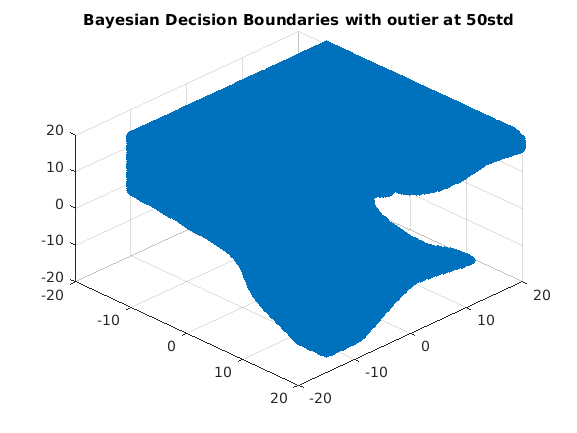

PlotNN_outlierA(g, points)
title('Bayesian Decision Boundaries with outier at 50std')

**5.Discuss in detail why or why not the neural network will ever be able to produce decision boundaries equivalent to the Bayes boundaries.**

Answer: Neural network will not be able to produce decision boundaries equivalent to the Bayes boundaries because neural network only has the  information about the training data we input and it can only assume decisions for the inputs outside the training data , which increases the chances of error to a higher extent where as for Bayes boundaries has  analytical description of the entire data.

The only scenario neural network can produce decision boundaries equivalent to the Bayes boundaries is when we input infinite data to neural network which is not possible .Since Bayes boundaries can give as an optimal classifier with minimal risks ,thus there will n need to find produce neural network boundaries.

 Q6 . **Discussion**

In the above plots, we have tried to demonstrate changes in the neural network boundaries and the distribution of changes in boundaries of particular class A. By adding the outlier data points the boundaries and distributions are changing significantly.

Neural Networks can be insensitive to less number of outliers due to the presence of other non-outliers points during the calculation of mean squared error points. Therefore, we have considered large number of outliers to demonstrate changes in the neural network boundaries. In general, bayesian classifier is highly sensitive to outlier data points. While in case of neural networks, the outlier data points should be at a higher distance from the mean of the distribution so that it significantly impacts the Mean Squared Error.

**7. Discuss the trade-offs that occur between generalizability and overfitting as the ratio of training data to test data is changed, i.e., for example from 90:10 to 10:90.**

Answer :

Case 1: If we divide training data and test data  in 90:10 ratio , there can be high chance of generalization of data and will produce high accuracy on real world data. But here there is case of overfitting where it memorizes from training set and evaluate based on this. Thus failing to provide a general understand .

Case 2:If we divide training data and test data in 10:90 ratio, there would be not much information to memorize thus reducing the chance of overfitting .But this model only succeeds if it provide high accuracy in the testing data 

function PlotNN_outlierA(results, points)

    % Boundary for points that lie in class A
    boundary_A = find(results(:, 1) > max(results(:, 2), results(:, 3)));
    
    % Points for boundary A
    result_A = points(boundary_A, :);

    % Plot the NN decision boundaries
    scatter3(result_A(:, 1), result_A(:, 2), result_A(:, 3), 'filled') 
    view([45, 45])
    hold off

end


% generating the outlier data points at random mahalanobis distances
function l = outlier_point(covar, mu, n, class)
    l =class
    for i=1:n
        
        [V, D] = eigs(cov(covar));
        std = sqrt(diag(D));
        
        %generating outlier in the direction of eigen vector of class
        data_point = randi(i)*std(1)*V(:,1) + mu;
        l = [l; data_point'];
    end
end

function [boundary_1, boundary_2,boundary_3] = NN_boundary(g,points)
    epsilon_NN_1 = 1e-1;
    epsilon_NN_2 = 1e-2; 
    decisionbound1 =  abs(g(:, 1) - g(:, 2));
    decisionbound2 =  abs(g(:, 2) - g(:, 3));
    decisionbound3 =  abs(g(:, 1) - g(:, 3));
    
    ind_boundary_1 = find(abs(g(:, 1)) <= epsilon_NN_1 & decisionbound2 < epsilon_NN_2);
    ind_boundary_2 = find(abs(g(:, 2)) <= epsilon_NN_1 & decisionbound3 < epsilon_NN_2);
    ind_boundary_3 = find(abs(g(:, 3)) <= epsilon_NN_1 & decisionbound1 < epsilon_NN_2);    
    boundary_1 = points(ind_boundary_1,:);
    boundary_2 = points(ind_boundary_2,:);
    boundary_3 = points(ind_boundary_3,:);        
end

function [] = Classes(randomClassASamples,muClassA,sigmaClassA,randomClassBSamples,muClassB,sigmaClassB,randomClassCSamples,muClassC,sigmaClassC,boundary_1,boundary_2,boundary_3, color)
    
     ellipsoid_plot(muClassA,sigmaClassA,[1 0 0])
     hold on
     ellipsoid_plot(muClassB,sigmaClassB,[0 1 0])
     ellipsoid_plot(muClassC,sigmaClassC,[0 1 1])
%     
    scatter3(randomClassASamples(:,1),randomClassASamples(:,2),randomClassASamples(:,3),'r.')
    scatter3(randomClassBSamples(:,1),randomClassBSamples(:,2),randomClassBSamples(:,3),'g.')
    scatter3(randomClassCSamples(:,1),randomClassCSamples(:,2),randomClassCSamples(:,3),'c.')
    plot3(boundary_1(:,1),boundary_1(:,2),boundary_1(:,3),'Marker',".","LineStyle","none","Color",color)
    plot3(boundary_2(:,1),boundary_2(:,2),boundary_2(:,3),'Marker',".","LineStyle","none","Color",color)
    plot3(boundary_3(:,1),boundary_3(:,2),boundary_3(:,3),'Marker',".","LineStyle","none","Color",color)
    hold off
    xlabel('X-axis')
    ylabel('Y-axis')
    zlabel('Z-axis')
    view([45 45])
end

function [] = ellipsoid_plot(mu,sigma,edge_color)
[V,D] = eigs(sigma);
std = sqrt(diag(D));

% obtaining position values using ellipsoid function, the ellipsoid
% function uses one, two and three standard deviation from the mean
[x1,y1,z1] = ellipsoid(0,0,0,std(1),std(2),std(3));
[x2,y2,z2] = ellipsoid(0,0,0,2*std(1),2*std(2),2*std(3));
[x3,y3,z3] = ellipsoid(0,0,0,3*std(1),3*std(2),3*std(3));    


% adjusting the position values of all the three different standard
% deviations

% plotting concentric ellipsoid 1 with one standard deviation

dim = [x1(:) y1(:) z1(:)]'; 
dim = V*dim + mu; % adjusting the mean
x1 = reshape(dim(1,:), size(x1));
y1 = reshape(dim(2,:), size(y1));
z1 = reshape(dim(3,:), size(z1));


surf(x1,y1,z1,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 2 with two standard deviation
dim = [x2(:) y2(:) z2(:)]';
dim = V*dim + mu;
x2 = reshape(dim(1,:), size(x2));
y2 = reshape(dim(2,:), size(y2));
z2 = reshape(dim(3,:), size(z2));


surf(x2,y2,z2,'FaceAlpha',0.05,'EdgeColor',edge_color);

% plotting concentric ellipsoid 3 with three standard deviation
dim = [x3(:) y3(:) z3(:)]';
dim = V*dim + mu;
x3 = reshape(dim(1,:), size(x3));
y3 = reshape(dim(2,:), size(y3));
z3 = reshape(dim(3,:), size(z3));


surf(x3,y3,z3,'FaceAlpha',0.05,'EdgeColor',edge_color);
end

function V = vol3D(Vaxis,Num)
% Build 3D volume of regular grid points 

    NV = Num;
    
    if length(Vaxis) == 2
        Vaxis = [Vaxis Vaxis Vaxis];
    end
    
    min_a = Vaxis(1);
    max_a = Vaxis(2);
    res = (max_a - min_a) / (NV - 1);
    %r = min_a: res: max_a;
    %r = r(:);
    rx = [Vaxis(1):(Vaxis(2) - Vaxis(1)) / (NV-1):Vaxis(2)]';
    ry = [Vaxis(3):(Vaxis(4) - Vaxis(3)) / (NV-1):Vaxis(4)]';
    rz = [Vaxis(5):(Vaxis(6) - Vaxis(5)) / (NV-1):Vaxis(6)]';
    x = zeros(3, length(rz)^3);
    k = 1;
    j = 1;
    
    for i = 1:length(rz):length(x)
        x(3, (i - 1) + (1: length(rz))) = rz;
        x(2, (i - 1) + (1: length(rz))) = ry(k) * ones(1, length(rz));
        x(1, (i - 1) + (1: length(rz))) = rx(j) * ones(1, length(rz));
        k = k + 1;
        if k > length(rz)
            k = 1;
            j = j + 1;
        end
    end
    x = x';
    V = x;

end
